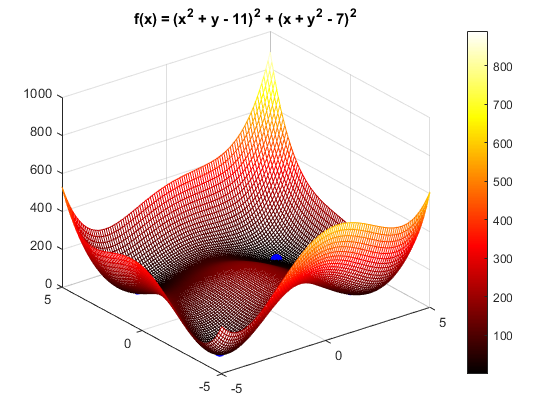

clear variables
X = [infsup(-5, 5);infsup(-5, 5)];
n = 100;
x_grid = linspace(inf(X(1)), sup(X(1)), n);
y_grid = linspace(inf(X(2)), sup(X(2)), n);
[xx, yy] = meshgrid(x_grid, y_grid);
zz = Himmel(xx, yy);
extr_val = [3, 2;-2.805118 3.131312;-3.779310 -3.283186;3.584428 -1.848126];
figure
mesh(xx, yy, zz)
colorbar
colormap("hot")
hold on
plot3(extr_val(1, 1), extr_val(1, 2), 0, 'ob', "MarkerSize", 8, "MarkerFaceColor", [0, 0, 1])
plot3(extr_val(2,1), extr_val(2,2), 0, 'ob', "MarkerSize", 8, "MarkerFaceColor", [0, 0, 1])
plot3(extr_val(3,1), extr_val(3,2), 0, 'ob', "MarkerSize", 8, "MarkerFaceColor", [0, 0, 1])
plot3(extr_val(4,1), extr_val(4,2), 0, 'ob', "MarkerSize", 8, "MarkerFaceColor", [0, 0, 1])
title('f(x) = (x^2 + y - 11)^2 + (x + y^2 - 7)^2')

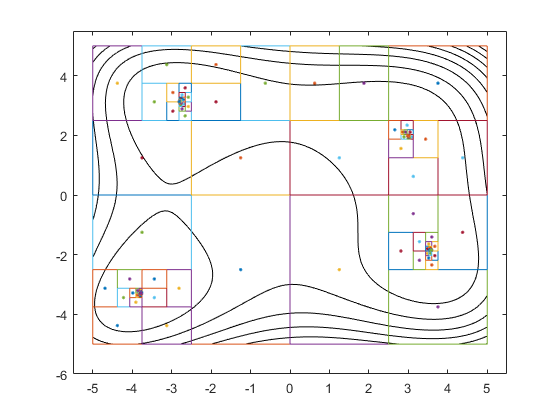

figure
contour(xx, yy, zz, 'k')
hold on 
[opt, worklist] = globopt0(X);
opt_int = worklist(1).Box;
min_est = inf;
max_est = inf;
for b = worklist
    if b.Estim < min_est
        opt_int = b.Box;
        min_est = b.Estim;
        max_est = b.EstimUp;
    end
    plotintval(b.Box, 'n')
    hold on
end

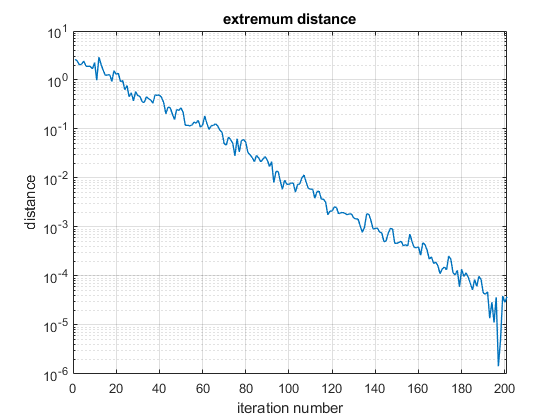

extr_val = extr_val';
dist_extr = zeros(1, size(worklist, 2));
rad_bars = dist_extr;
for i=1:size(worklist, 2)
    dist_extr(1, i) = min(vecnorm(extr_val - mid(worklist(i).Box)));
    rad_bars(1, i) = max(rad(worklist(i).Box));
end
figure
semilogy(dist_extr, "LineWidth", 1)
hold on
grid on
title('extremum distance')
xlabel('iteration number')
ylabel('distance')
xlim([0 size(worklist, 2)])

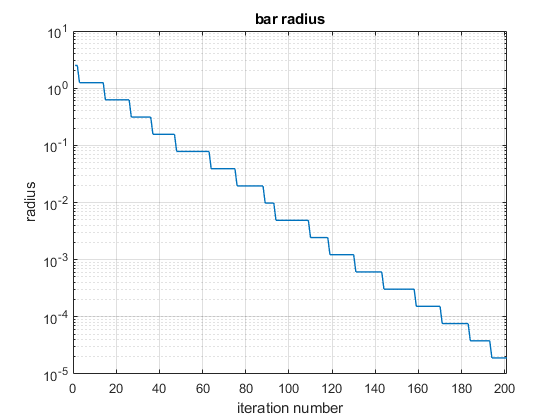

figure
semilogy(rad_bars, "LineWidth", 1)
hold on
grid on
title('bar radius')
xlabel('iteration number')
ylabel('radius')
xlim([0 size(worklist, 2)])